# Deep Learning: Motion data Analysis_#3

clc; clear; close all

#### **Load Data**

load posdata
load frame

#### **Data Information**

- The movement data of cuttle fish's body parts from 5 videos. 

- Each video consists of 20 frames

- Tracked (x, y) position of 5 body parts (dorsal mantle end,  left eye, right eye, left tentacle club tips, right tentacle club tips)

% Define Variables
n_videos    = 5;
n_position  = 2;
n_frames    = 20;
n_joint     = 5;

% Define Body Parts
joint       = {'dorsal mantle end';
               'left eyes';
               'right eyes';
               'left tentacle club tips';
               'Right tentacle club tips'};

#### Data Organization

% Convert data to numeric array
% time steps x (position * joint) x videos
pos_tmp     = cellfun(@struct2cell, posdata, 'UniformOutput', false);
pos_tmp     = cellfun(@cell2mat,    pos_tmp, 'UniformOutput', false);
Pos         = cellfun(@(data) data', pos_tmp, 'UniformOutput', false);
Pos         = cat(3, Pos{:});

size(Pos)

ans =     20    10     5


nanidx      = isnan(Pos);
interp      = repmat( mean(Pos, 'omitnan'),20,1 ) .* nanidx;
Pos(nanidx) = interp(nanidx);

clear pos_tmp nanidx interp

#### Data Augmentation

(1) Time Point Augmentation

Pos_aug_time = nan((n_frames-1)*10, n_joint*2, n_videos);

for i_video = 1:n_videos
    for i_joint = 1:n_joint*2
        tmp_data = Pos(:, i_joint, i_video);
        aug_data = [];
        for i_frames = 1:n_frames-1
            aug_time = linspace(tmp_data(i_frames), tmp_data(i_frames+1), 11);
            aug_data = [aug_data; aug_time(1:end-1)'];
        end
        Pos_aug_time(:, i_joint, i_video) = aug_data;
    end
end

% augmented time steps x position x joint x videos
Pos_aug = reshape(Pos_aug_time, (n_frames-1)*10, [], n_joint, n_videos);
size(Pos_aug)

ans =    190     2     5     5


clear tmp_data aug_data aug_time

(2) Rotation Based Augmentation

angle         = deg2rad(-9.8:0.2:10); 
Pos_aug_video = nan((n_frames-1)*10, 2, n_joint, n_videos*length(angle));

for i_video = 1:n_videos
    for i_joint = 1:n_joint
        tmp_data = Pos_aug(:,:, i_joint, i_video)';
        aug_data = [];
        for rot = 1:length(angle)
            % Rotation Matrix
            R = [cos(angle(rot)) -sin(angle(rot)); ...
                sin(angle(rot))  cos(angle(rot))];

`!!!Fill the blank!!!`

            aug_rot  = R * tmp_data;

ans =    190     2     5   500


            aug_data = cat(4, aug_data, aug_rot');
        end
        Pos_aug_video(:,:,i_joint,(i_video-1)*length(angle)+1:i_video*length(angle)) = aug_data;
    end
end

% augmented time steps x position x joint x augmented videos

ans =          190           2        2500


size(Pos_aug_video)

clear angle tmp_data aug_data aug_rot R rot ...
      i_video i_frames i_joint Pos_aug_time Pos_aug

% time steps x position x (joint * videos)
Pos_aug = reshape( Pos_aug_video, size(Pos_aug_video,1), size(Pos_aug_video,2), size(Pos_aug_video,3) * size(Pos_aug_video,4));
size(Pos_aug)

**Visualization of the Augmented Video Data**

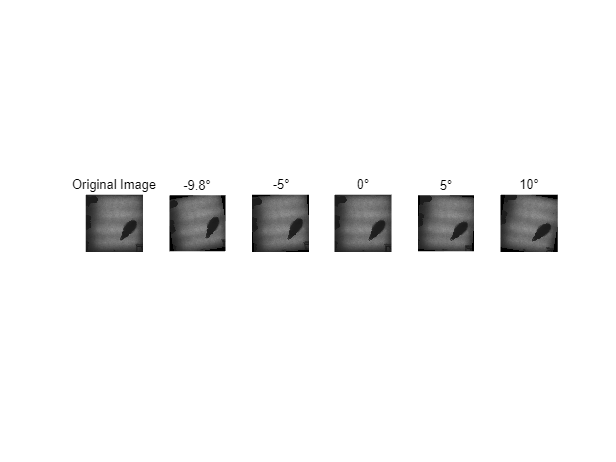

selected_video = 1;
selected_frame = 1;
representative_angles = [-9.8, -5, 0, 5, 10]; % Select representative angles in degrees

% Extract the original image
original_image = frame{selected_video, selected_frame};

% Plot the original image
figure('Name', 'Original Image and Rotations', 'NumberTitle', 'off');
subplot(1, length(representative_angles) + 1, 1);
imshow(original_image);
title('Original Image');

% Rotate and visualize selected angles
for i = 1:length(representative_angles)
    theta = deg2rad(representative_angles(i)); % Convert to radians
    R = [cos(theta) -sin(theta); sin(theta) cos(theta)]; % Rotation matrix

    % Rotate the image
    rotated_image = zeros(size(original_image), 'uint8');
    [rows, cols, channels] = size(original_image);
    center_x = cols / 2;
    center_y = rows / 2;

    for x = 1:cols
        for y = 1:rows
            % Translate pixel to origin
            translated_coord = [x - center_x; y - center_y];

            % Apply inverse rotation matrix
            original_coord = R \ translated_coord;

            % Translate back
            original_coord(1) = original_coord(1) + center_x;
            original_coord(2) = original_coord(2) + center_y;

            % Nearest-neighbor interpolation
            orig_x = round(original_coord(1));
            orig_y = round(original_coord(2));

            if orig_x >= 1 && orig_x <= cols && orig_y >= 1 && orig_y <= rows
                rotated_image(y, x, :) = original_image(orig_y, orig_x, :);
            end

        end
    end

    % Plot the rotated image
    subplot(1, length(representative_angles) + 1, i + 1);
    imshow(rotated_image);
    title([num2str(representative_angles(i)), '°']);
end

### **LSTM (**Long Short-Term Memory)

#### Data Preparation for LSTM

% Normalization
Pos_norm = (Pos_aug - mean(Pos_aug,2)) ./ std(Pos_aug,0,2);

X = {};
for i = 1:size(Pos_norm, 3)

ans = 5×1 cell 배열
    {'Right tentacle club tips'}
    {'dorsal mantle end'       }
    {'left eyes'               }
    {'left tentacle club tips' }
    {'right eyes'              }


    X{i,1} = Pos_norm(:,:,i)';
end

% Make labels
y = [repmat("dorsal mantle end",        [size(Pos_aug_video,4) 1]); ...
     repmat("left eyes",                [size(Pos_aug_video,4) 1]); ...
     repmat("right eyes",               [size(Pos_aug_video,4) 1]); ...
     repmat("left tentacle club tips",  [size(Pos_aug_video,4) 1]); ...
     repmat("Right tentacle club tips", [size(Pos_aug_video,4) 1])
     ];

y = categorical(y);
categories(y)

% Shuffle
n_sample  = length(y);
idx       = randperm(n_sample);
X         = X(idx);
y         = y(idx);

% Data Partition
prop      = 0.1; % 10% for validation, 10% for testing, remaining 80% training
partition = n_sample * prop;

idx_val   = idx(1:partition);
idx_te    = idx(partition+1:partition*2);
idx_tr    = idx(partition*2+1:end);


`!!!Fill the blank!!!`

X_train   = X(idx_tr);
y_train   = y(idx_tr);

X_test    = X(idx_te);
y_test    = y(idx_te);

X_val     = X(idx_val);
y_val     = y(idx_val);

#### LSTM Classification (5-class)

- (1) Training

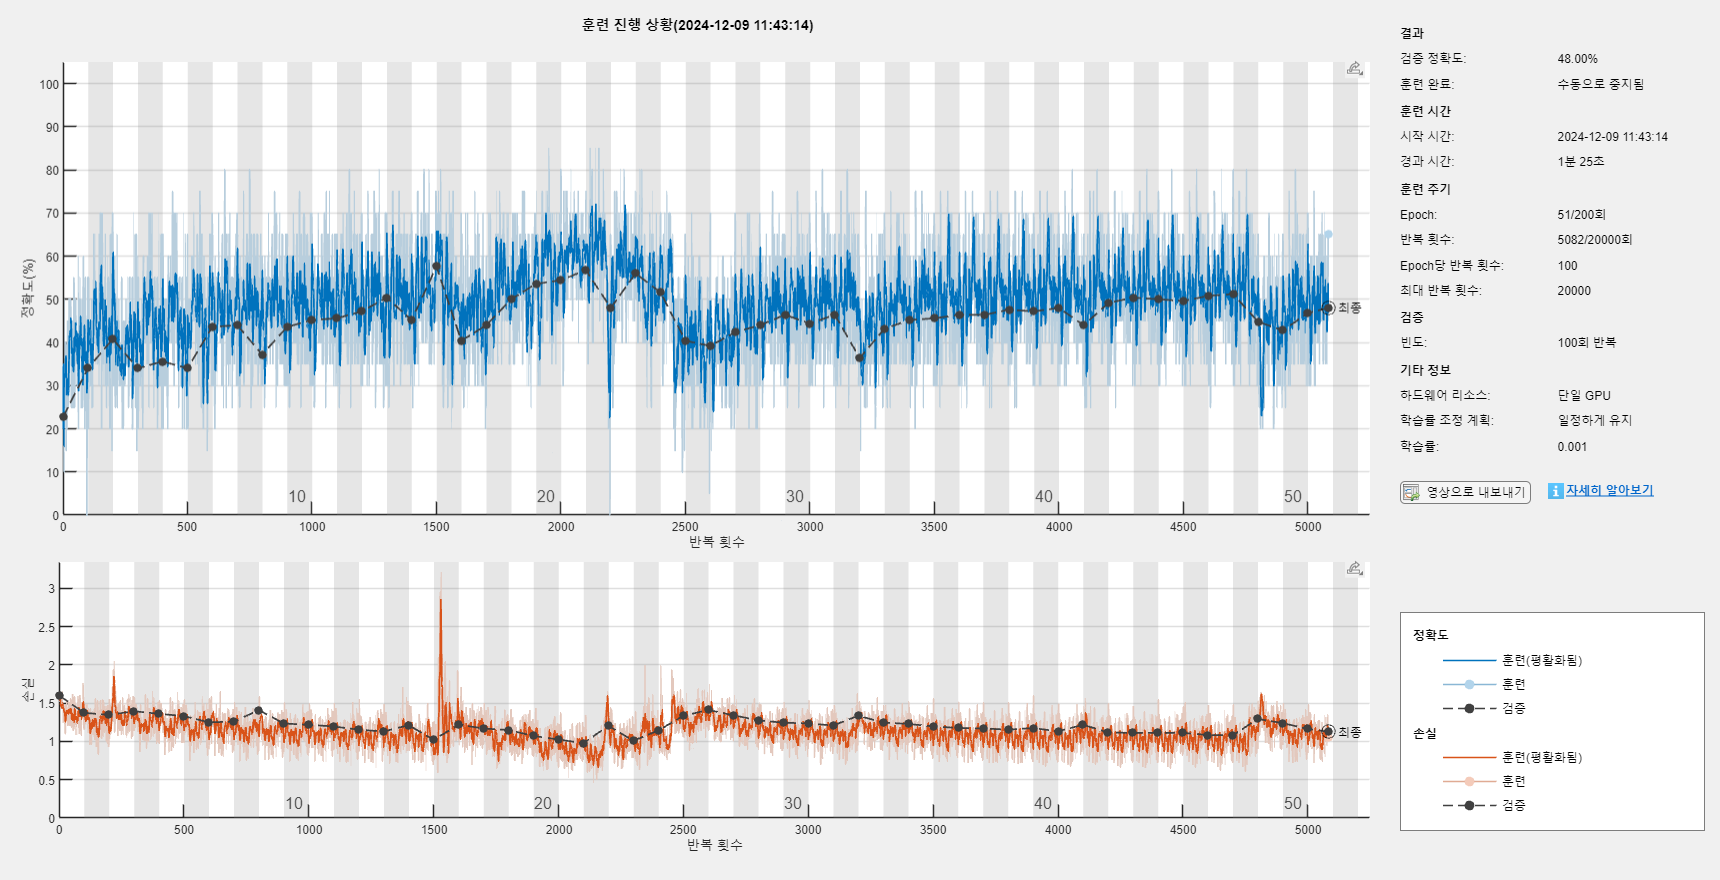

numHiddenUnits = 100; % Hyperparameter
numClasses     = numel(categories(y));

layers = [
    sequenceInputLayer(n_position, 'Normalization', 'zscore')
    lstmLayer(numHiddenUnits, 'OutputMode', 'last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];

options = trainingOptions('adam', ...

                          'InitialLearnRate', 0.001, ...
                          'MaxEpochs', 200, ...
                          'MiniBatchSize', 20, ...
                          'Shuffle','never', ...
                          'ValidationData', {X_val, y_val}, ...
                          'ValidationFrequency', 100, ...
                          'Verbose',false, ...

The classification accuracy is 47.2%


                          'Plots','training-progress');

`!!!Fill the blank!!!`

% Train LSTM Network
net = trainNetwork(X_train, y_train, layers, options);

- (2) Test

`!!!Fill the blank!!!`

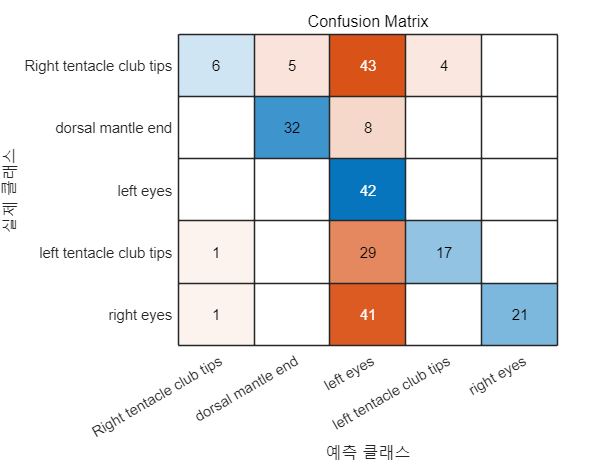

% Prediction
y_pred  = classify(net, X_test);
acc     = 100 * sum(y_pred == y_test) / numel(y_test);

disp(['The classification accuracy is ' num2str(acc), '%']);

% Confusion Matrix
figure;
conf_mat = confusionmat(y_test, y_pred);
confusionchart(conf_mat, categories(y))
title('Confusion Matrix')